## **Simulação - Transmissão de imagem Wi-Fi**

#### Alunos: Mariana Olm e Thyago Piske

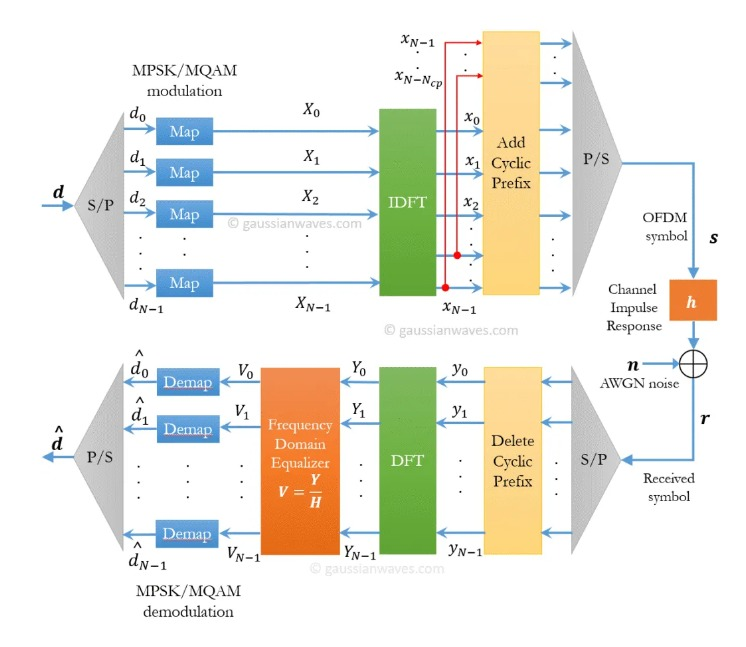

**1) Dados de entrada (imagem)**

**i) **Conversor A/D

- Conversão da imagem para a escala cinza e criação da sequência de bits (bitstream)

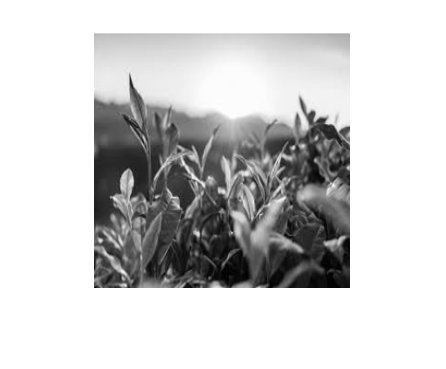

img = imread('imagem.png');
resized = imresize(img, [256 256]);

img_gray = rgb2gray(resized);

figure;
imshow(img_gray)

img_bits = reshape((dec2bin(img_gray, 8) - '0').', 1, []);
orig_class = class(img_gray);
orig_size = size(img_gray);

**2) Codificação convolucional**

inserir imagens e explicação

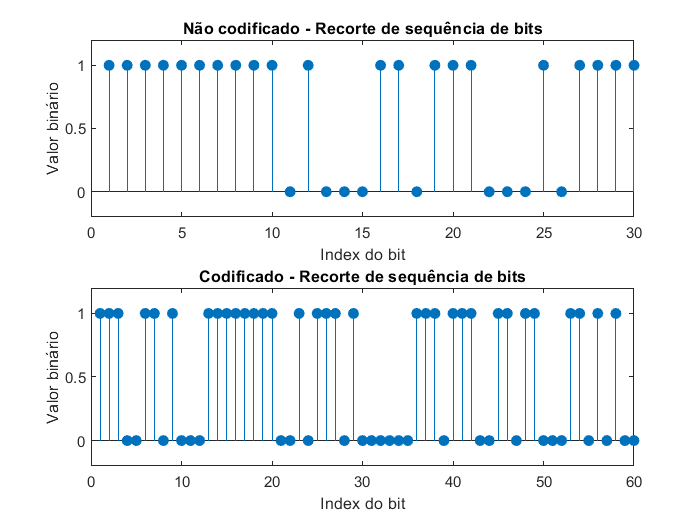

% Parâmetros da codificação
constraint_length = 7;  % Constraint length (K)
generator_polynomials = [133, 171];  % Generator polynomials in octal form

trellis = poly2trellis(constraint_length, generator_polynomials);
sinal_codificado = convenc(img_bits, trellis);

figure; 

subplot(2, 1, 1);
stem(img_bits(1:30), 'filled');
ylim([-0.2 1.2]);
title('Não codificado - Recorte de sequência de bits');
xlabel('Index do bit');
ylabel('Valor binário');

subplot(2, 1, 2);
stem(sinal_codificado(1:60), 'filled');
ylim([-0.2 1.2]);
title('Codificado - Recorte de sequência de bits');
xlabel('Index do bit');
ylabel('Valor binário');

**3) Mapeamento 4-QAM**

- Nível de modulação $\to M=2^n$, sendo $n$ a quantidade de bits/símbolo

Como têm-se $n=2$, o nível de modulação $M=4$, portanto será realizado um mapeamento 4-QAM.

Existem $2^N$ bits de informação na imagem e cada símbolo possui 2 bits, portanto terão $2^{N-1}$ símbolos no total, podendo eles se enquadrar em apenas 4 pontos do mapa de símbolos do 4-QAM.

M = 4;

sinal_modulado_nao_codificado = qammod(img_bits', M, 'InputType', 'bit');
numero_simbolos_nao_codificados = length(sinal_modulado_nao_codificado);

sinal_modulado_codificado = qammod(sinal_codificado', M, 'InputType', 'bit');
numero_simbolos_codificados = length(sinal_modulado_codificado);

Mapa de constelação dos bits mapeados

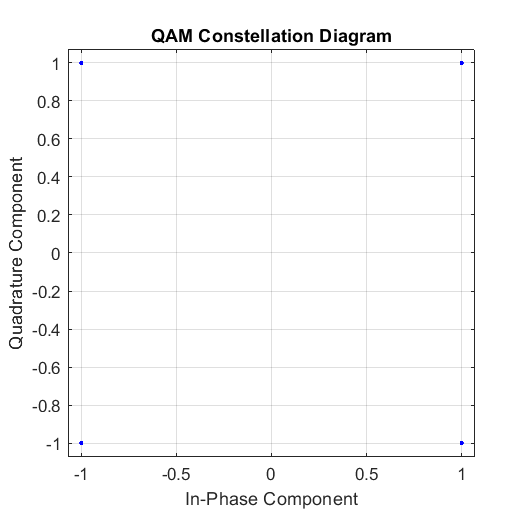

figure;
scatterplot(sinal_modulado_nao_codificado);
title('QAM Constellation Diagram');
xlabel('In-Phase Component');
ylabel('Quadrature Component');
grid on;

**4) Paralelização dos dados**

53 subportadoras com dados

numero_simbolos_OFDM_nao_codificados = ceil(numero_simbolos_nao_codificados / 53);
numero_simbolos_OFDM_codificados = ceil(numero_simbolos_codificados / 53);

% Matriz contendo 53 linhas (das subportadoras) e N colunas, sendo cada
% coluna um pacote de dados transmitido
sinal_modulado_nao_codificado = [sinal_modulado_nao_codificado; zeros(numero_simbolos_OFDM_nao_codificados * 53 - length(sinal_modulado_nao_codificado), 1)];
sinal_modulado_matriz_nao_codificado = reshape(sinal_modulado_nao_codificado, 53, []);

sinal_modulado_codificado = [sinal_modulado_codificado; zeros(numero_simbolos_OFDM_codificados * 53 - length(sinal_modulado_codificado), 1)];
sinal_modulado_matriz_codificado = reshape(sinal_modulado_codificado, 53, []);

**5) OFDM **

% Parâmetros da OFDM
numSC = 64; % Número de subcarries
cpLen = 16; % Cyclic Prefix

% Não codificado
ofdm_mod_nao_codificado = comm.OFDMModulator('FFTLength',numSC,'CyclicPrefixLength',cpLen, 'NumSymbols', numero_simbolos_OFDM_nao_codificados);
tx_sig_nao_codificado = ofdm_mod_nao_codificado(sinal_modulado_matriz_nao_codificado);

% Codificado
ofdm_mod_codificado = comm.OFDMModulator('FFTLength',numSC,'CyclicPrefixLength',cpLen, 'NumSymbols', numero_simbolos_OFDM_codificados);
tx_sig_codificado = ofdm_mod_codificado(sinal_modulado_matriz_codificado);


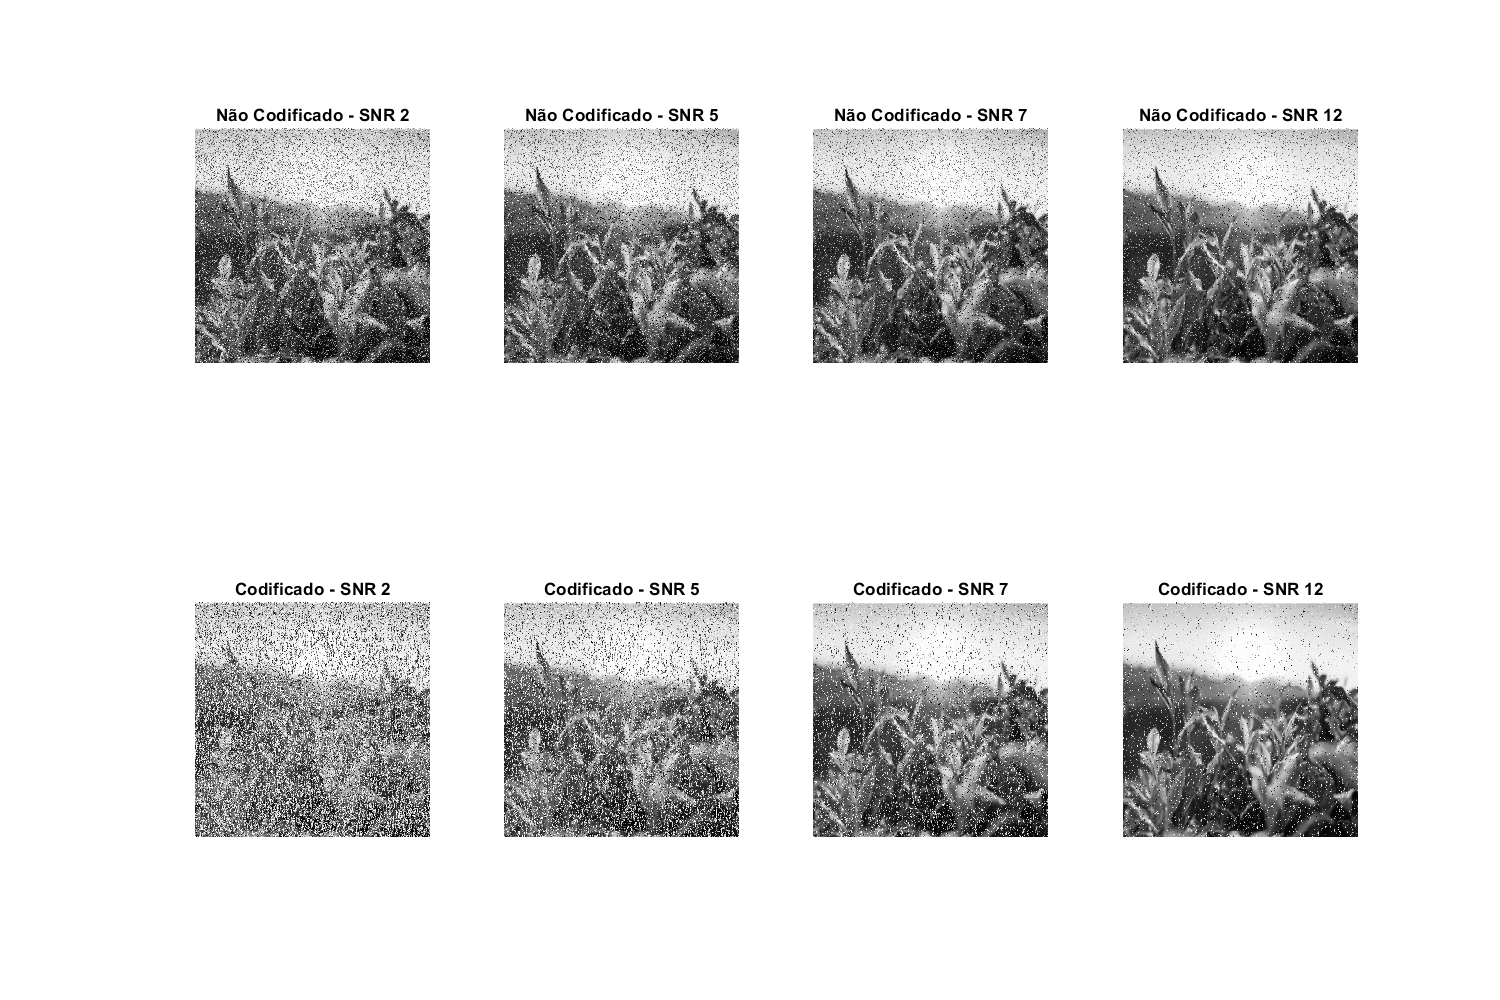


snr_ber = 1:1:14; % Valores de SNR para iterar
num_snr = length(snr_ber);

ber_nao_codificado = zeros(size(snr_ber)); 
num_erros_nao_codificado = zeros(size(snr_ber));
ber_codificado = zeros(size(snr_ber)); 
num_erros_codificado = zeros(size(snr_ber));

% Inicializa células para armazenar as imagens resultantes
images_nao_codificado = cell(1, num_snr);
images_codificado = cell(1, num_snr);

% Loop através dos valores de SNR
for i = 1:num_snr
    snr = snr_ber(i);
    
    % Adição de white gaussian noise no sinal
    rx_sig_nao_codificado = awgn(tx_sig_nao_codificado, snr, 'measured');
    rx_sig_codificado = awgn(tx_sig_codificado, snr, 'measured');
    
    % Não codificado
    ofdm_demod_nao_codificado = comm.OFDMDemodulator('FFTLength', numSC, 'CyclicPrefixLength', cpLen, 'NumSymbols', numero_simbolos_OFDM_nao_codificados);
    ofdm_demodulado_nao_codificado = ofdm_demod_nao_codificado(rx_sig_nao_codificado);
    sinal_demodulado_nao_codificado = qamdemod(ofdm_demodulado_nao_codificado, M, 'OutputType', 'bit');
    sinal_demodulado_serial_nao_codificado = reshape(sinal_demodulado_nao_codificado, 1, []);
    img_output_nao_codificado = sinal_demodulado_serial_nao_codificado(1, 1:length(img_bits));
    
    % Codificado
    tbdepth = 1;
    ofdm_demod_codificado = comm.OFDMDemodulator('FFTLength', numSC, 'CyclicPrefixLength', cpLen, 'NumSymbols', numero_simbolos_OFDM_codificados);
    ofdm_demodulado_codificado = ofdm_demod_codificado(rx_sig_codificado);
    sinal_demodulado_codificado = qamdemod(ofdm_demodulado_codificado, M, 'OutputType', 'bit');
    sinal_demodulado_serial_codificado = reshape(sinal_demodulado_codificado, 1, []);
    sinal_decodificado = vitdec(sinal_demodulado_serial_codificado, trellis, tbdepth, 'trunc', 'hard');
    img_output_codificado = sinal_decodificado(1, 1:length(img_bits));
    
    % Reconstrução das imagens
    reconstructed_nao_codificado = reshape(typecast(uint8(bin2dec(char(reshape(img_output_nao_codificado, 8, [])+'0').')), orig_class), orig_size);
    reconstructed_codificado = reshape(typecast(uint8(bin2dec(char(reshape(img_output_codificado, 8, [])+'0').')), orig_class), orig_size);
    
    % Calcula BER
    [num_erros_nao_codificado(i), ber_nao_codificado(i)] = biterr(img_bits,img_output_nao_codificado);
    [num_erros_codificado(i),ber_codificado(i)] = biterr(img_bits,img_output_codificado);
    
    % Armazena imagens
    images_nao_codificado{i} = reconstructed_nao_codificado;
    images_codificado{i} = reconstructed_codificado;
end

fig = figure();
set(fig, 'Position', [100, 100, 1200, 800]); 
snr_list = [2, 5, 7, 12];
num_snr_plot = length(snr_list);

for i = 1:num_snr_plot
    snr = snr_list(i);
    
    subplot(2, num_snr_plot, i);
    imshow(images_nao_codificado{i});
    title(['Não Codificado - SNR ', num2str(snr)]);
    
    subplot(2, num_snr_plot, num_snr_plot + i);
    imshow(images_codificado{i});
    title(['Codificado - SNR ', num2str(snr)]);
end

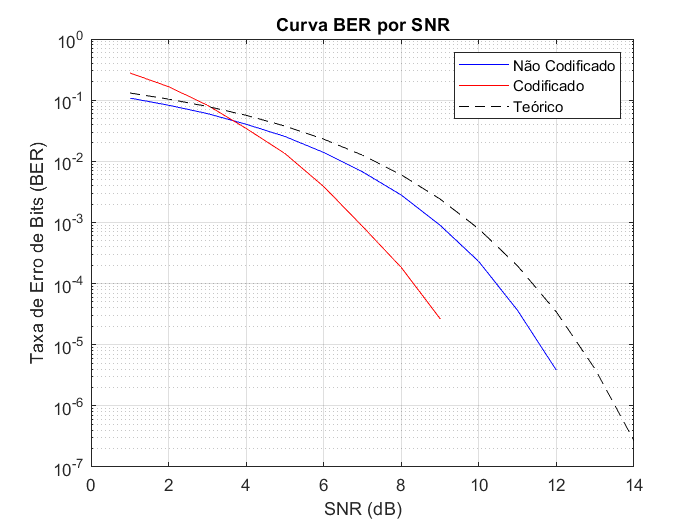

% Cálculo do BER teórico do mapeamento 4-QAM
snr_linear = 10.^(snr_ber/10);  % Converter SNR de dB para linear
EbNo = snr_linear ./ log2(M);   % Calcular Eb/No linear
EbNo_dB = 10 .* log10(EbNo);    % Converter Eb/No para dB

ber_teorico = berawgn(EbNo_dB,'QAM',M);

% Plot da curva de BER por SNR
figure()
semilogy(snr_ber, ber_nao_codificado, 'b-'); % BER para dados não codificados
hold on;
semilogy(snr_ber, ber_codificado, 'r-'); % BER para dados codificados
semilogy(snr_ber, ber_teorico, 'k--'); % BER teórica
xlabel('SNR (dB)');
ylabel('Taxa de Erro de Bits (BER)');
legend('Não Codificado', 'Codificado', 'Teórico');
title('Curva BER por SNR');
grid on;